# Machine Learning: Programming Exercise 1

## Linear Regression

In this exercise, you will implement linear regression and get to see it work on data.

### Files needed for this exercise

- `ex1.mlx` - MATLAB Live Script that steps you through the exercise

- ex1data1.txt - Dataset for linear regression with one variable

- ex1data2.txt - Dataset for linear regression with multiple variables

- `submit.m` - Submission script that sends your solutions to our servers

- *`warmUpExercise.m` - Simple example function in MATLAB

- *`plotData.m` - Function to display the dataset

- *`computeCost.m` - Function to compute the cost of linear regression

- *`gradientDescent.m` - Function to run gradient descent

- **`computeCostMulti.m` - Cost function for multiple variables

- **`gradientDescentMulti.m` - Gradient descent for multiple variables

- **`featureNormalize.m `- Function to normalize features

- **`normalEqn.m` - Function to compute the normal equations

****indicates files you will need to complete***

*****indicates optional exercises***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex1' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                       ex1.mlx                 gradientDescent.m       submit.m                
..                      ex1_companion.mlx       gradientDescentMulti.m  token.mat               
.MATLABDriveTag         ex1data1.txt            lib                     warmUpExercise.m        
computeCost.m           ex1data2.txt            normalEqn.m             
computeCostMulti.m      featureNormalize.m      plotData.m              



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README.mlx` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README.mlx` and have checked for an existing solution before seeking help on the discussion forums.

## 1. A simple MATLAB function

The first part of this script gives you practice with MATLAB syntax and the homework submission process. In the file `warmUpExercise.m`, you will find the outline of a MATLAB function. Modify it to return a 5 x 5 identity matrix by filling in the following code:

When you are finished, save `warmUpExercise.m`, then run the code contained in this section to call `warmUpExercise().` 

**5x5 Identity Matrix:**

warmUpExercise()

ans =      1     0     0     0     0
     0     1     0     0     0
     0     0     1     0     0
     0     0     0     1     0
     0     0     0     0     1


You should see output similar to the following:

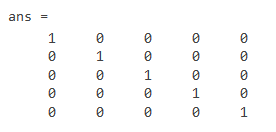

You can toggle between right-hand-side output and in-line output for printing results and displaying figures inside a Live Script by selecting the appropriate box in the upper right of the Live Editor window. 

### 1.1 Submitting Solutions

After completing a part of the exercise, you can submit your solutions for that section by running the section of code below, which calls the `submit.m` script. Your score for each section will then be displayed as output. **Enter your login and your unique submission token *****inside the command window***** when prompted. For future submissions of this exercise, you will only be asked to confirm your credentials.** Your submission token for each exercise is found in the corresponding homework assignment course page. New tokens can be generated if you are experiencing issues with your current token. You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter your login and token when prompted.*

## 2. Linear regression with one variable

In this part of this exercise, you will implement linear regression with one variable to predict profits for a food truck. Suppose you are the CEO of a restaurant franchise and are considering different cities for opening a new outlet. The chain already has trucks in various cities and you have data for profits and populations from the cities. You would like to use this data to help you select which city to expand to next.

The file `ex1data1.txt` contains the dataset for our linear regression problem. The first column is the population of a city and the second column is the profit of a food truck in that city. A negative value for profit indicates a loss. This script has already been set up to load this data for you.

### 2.1 Plotting the data

Before starting on any task, it is often useful to understand the data by visualizing it. For this dataset, you can use a scatter plot to visualize the data, since it has only two properties to plot (profit and population). Many other problems that you will encounter in real life are multi-dimensional and can't be plotted on a 2-d plot.

Run the code below to load the dataset from the data file into the variables X and y:

data = load('ex1data1.txt'); % read comma separated data
X = data(:, 1); y = data(:, 2);

Your job is to complete `plotData.m` to draw the plot; modify the file and fill in the following code:

Once you are finished, save `plotData.m,` and execute the code in this section which will call `plotData`. 

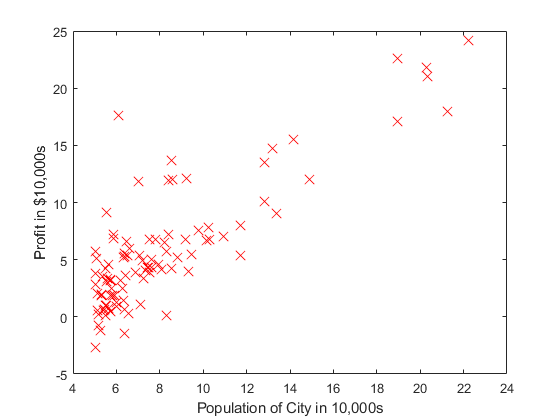

plotData(X,y)

The resulting plot should appear as in Figure 1 below:

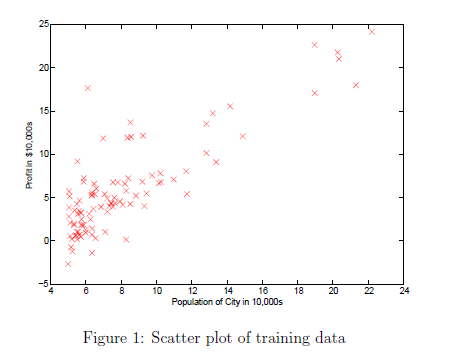

To learn more about the `plot` command, you can run the command `help plot` at the command prompt, type `plot()` inside the MATLAB Live Editor and click on the "(?)" tooltip, or you can search the [MATLAB documentation](https://www.mathworks.com/help/matlab/) for "plot". Note that to change the markers to red x's in the plot, we used the option: **'**`rx'` together with the `plot` command, i.e., 

### 2.2 Gradient Descent

In this section, you will fit the linear regression parameters to our dataset using gradient descent.

#### 2.2.1 Update Equations

The objective of linear regression is to minimize the cost function


$$J\left(\theta \right)=\frac{1}{2m}\sum_{i=1}^m {\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)}^2 \;$$


where the hypothesis $h_{\theta}(x)$ is given by the linear model


$$h_{\theta } \left(x\right)=\theta^T x=\theta_0 +\theta_1 x_1$$


Recall that the parameters of your model are the $\theta$ values. These are the values you will adjust to minimize cost $J(\theta)$. One way to do this is to use the batch gradient descent algorithm. In batch gradient descent, each iteration performs the update


$$\theta_j :=\theta_j -\alpha \frac{\;1}{m}\sum_{i=1}^m \;\left(h_{\theta \;} \left(x^{\left(i\right)} \right)-y^{\left(i\right)} \right)x_j^{\left(i\right)} \;\;\;\;\;\;\;\left(\textrm{simultaneously}\;\textrm{update}\;\theta_{j\;} \;\textrm{for}\;\textrm{all}\;j\right)$$


With each step of gradient descent, your parameters $j$ come closer to the optimal values that will achieve the lowest cost $J(\theta)$.

**Implementation Note:** We store each example as a row in the the `X` matrix in MATLAB. To take into account the intercept term ($\theta_0$), we add an additional first column to `X` and set it to all ones. This allows us to treat $\theta_0$ as simply another 'feature'.

#### 2.2.2 Implementation

In this script, we have already set up the data for linear regression. In the following lines, we add another dimension to our data to accommodate the $\theta_0$ intercept term. Run the code below to initialize the parameters to 0 and the learning rate `alpha` to 0.01. 

m = length(X); % number of training examples
X = [ones(m,1),data(:,1)]; % Add a column of ones to x
theta = zeros(2, 1); % initialize fitting parameters
iterations = 1500;
alpha = 0.01;

#### 2.2.3 Computing the cost $\mathit{\mathbf{J}}\left(\theta \right)$

As you perform gradient descent to minimize the cost function $J\left(\theta \right)$, it is helpful to monitor the convergence by computing the cost. In this section, you will implement a function to calculate $J\left(\theta \right)$ so you can check the convergence of your gradient descent implementation.

    Your next task is to complete the code in the file `computeCost.m`, which is a function that computes $J\left(\theta \right)$. As you are doing this, remember that the variables `X` and `y` are not scalar values, but matrices whose rows represent the examples from the training set.

    Once you have completed the function definition, run this section. The code below will call `computeCost` once using $\theta$ initialized to zeros, and you will see the cost printed to the screen. You should expect to see a cost of 32.07 for the first output below:

% Compute and display initial cost with theta all zeros
computeCost(X, y, theta)

ans = 32.0727

Next we call `computeCost` again, this time with non-zero `theta` values as an additional test. You should expect to see an output of 54.24 below:

% Compute and display initial cost with non-zero theta
computeCost(X, y,[-1; 2])

ans = 54.2425

If the outputs above match the expected values, you can submit your solution for assessment. If the outputs do not match or you receive an error, check your cost function for mistakes, then rerun this section once you have addressed them.

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

#### 2.2.4 Gradient descent

Next, you will implement gradient descent in the file `gradientDescent.m`. The loop structure has been written for you, and you only need to supply the updates to $\theta$ within each iteration.

    As you program, make sure you understand what you are trying to optimize and what is being updated. Keep in mind that the cost $J\left(\theta \right)$ is parameterized by the vector $\theta$, not $X$ and $y$. That is, we minimize the value of $J\left(\theta \right)$ by changing the values of the vector $\theta$, not by changing $X$ or $y$. Refer to the equations given earlier and to the video lectures if you are uncertain.

A good way to verify that gradient descent is working correctly is to look at the value of `J` and check that it is decreasing with each step. The starter code for `gradientDescent.m` calls `computeCost` on every iteration and prints the cost. Assuming you have implemented gradient descent and `computeCost` correctly, your value of $J\left(\theta \right)$ should never increase, and should converge to a steady value by the end of the algorithm.

    After you are finished, run this execute this section. The code below will use your final parameters to plot the linear fit. The result should look something like Figure 2 below:

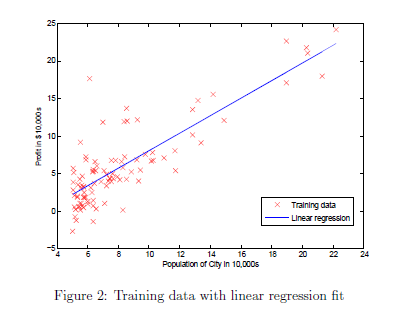    

    Your final values for $\theta$ will also be used to make predictions on profits in areas of 35,000 and 70,000 people.

% Run gradient descent:
% Compute theta
theta = gradientDescent(X, y, theta, alpha, iterations);

**********
Debug purposes:
Theta computed from gradient descent:-3.630291,1.166362
Iteration: 1 
Cost: 4.483365
 ********************
Debug purposes:
Theta computed from gradient descent:-3.630770,1.166410
Iteration: 2 
Cost: 4.483342
 ********************
Debug purposes:
Theta computed from gradient descent:-3.631248,1.166458
Iteration: 3 
Cost: 4.483319
 ********************
Debug purposes:
Theta computed from gradient descent:-3.631725,1.166506
Iteration: 4 
Cost: 4.483296
 ********************
Debug purposes:
Theta computed from gradient descent:-3.632201,1.166554
Iteration: 5 
Cost: 4.483274
 ********************
Debug purposes:
Theta computed from gradient descent:-3.632676,1.166602
Iteration: 6 
Cost: 4.483251
 ********************
Debug purposes:
Theta computed from gradient descent:-3.633150,1.166650
Iteration: 7 
Cost: 4.483228
 ********************
Debug purposes:
Theta computed from gradient descent:-3.633623,1.166697
Iteration: 8 
Cost: 4.483206
 ********************
Debug


% Print theta to screen
% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f,\n%f',theta(1),theta(2))

Theta computed from gradient descent:
-3.878051,
1.191253

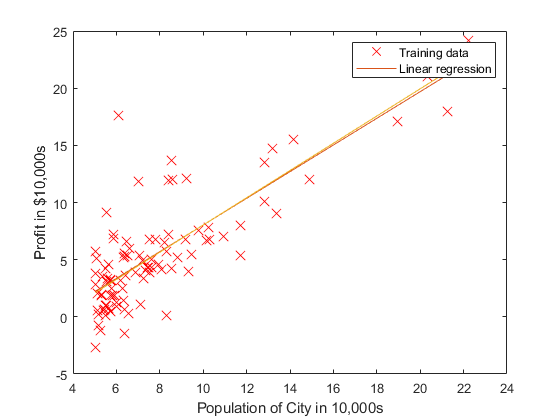


% Plot the linear fit
hold on; % keep previous plot visible
plot(X(:,2), X*theta, '-')
legend('Training data', 'Linear regression')
hold off % don't overlay any more plots on this1 figure


% Predict values for population sizes of 35,000 and 70,000
predict1 = [1, 3.5] *theta;
fprintf('For population = 35,000, we predict a profit of %f\n', predict1*10000);

For population = 35,000, we predict a profit of 2913.325861


predict2 = [1, 7] * theta;
fprintf('For population = 70,000, we predict a profit of %f\n', predict2*10000);

For population = 70,000, we predict a profit of 44607.163473


    Note the way that the lines above use matrix multiplication, rather than explicit summation or looping, to calculate the predictions. This is an example of *code vectorization* in MATLAB. 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then enter or confirm your login and token when prompted.*

### 2.3 Debugging

Here are some things to keep in mind as you implement gradient descent: 

- MATLAB array indices start from one, not zero. If you're storing $\theta_0$ and $\theta_1$ in a vector called `theta`, the values will be `theta(1)` and `theta(2)`.

- If you are seeing many errors at runtime, inspect your matrix operations to make sure that you're adding and multiplying matrices of compatible dimensions. Printing the dimensions of variables with the `size` command will help you debug.

- By default, MATLAB interprets math operators to be matrix operators. This is a common source of size incompatibility errors. If you don't want matrix multiplication, you need to add the "dot" notation to specify this to MATLAB. For example, `A*B` does a matrix multiply, while `A.*B` does an element-wise multiplication.

### 2.4 Visualizing $J(\theta)$

To understand the cost function $J(\theta)$ better, you will now plot the cost over a 2-dimensional grid of $\theta_0$ and $\theta_1$ values. You will not need to code anything new for this part, but you should understand how the code you have written already is creating these images.

    In the next step, there is code set up to calculate $J(\theta)$ over a grid of values using the `computeCost` function that you wrote. 

% Visualizing J(theta_0, theta_1):
% Grid over which we will calculate J
theta0_vals = linspace(-10, 10, 100);
theta1_vals = linspace(-1, 4, 100);

% initialize J_vals to a matrix of 0's
J_vals = zeros(length(theta0_vals), length(theta1_vals));

% Fill out J_vals
for i = 1:length(theta0_vals)
    for j = 1:length(theta1_vals)
    	  t = [theta0_vals(i); theta1_vals(j)];
    	  J_vals(i,j) = computeCost(X, y, t);
    end
end

    After the code above is executed, you will have a 2-D array of $J(\theta)$ values. The code below will then use these values to produce surface and contour plots of $J(\theta)$ using the `surf` and `contour` commands. Run the code in this section now. The resulting plots should look something like the figure below.

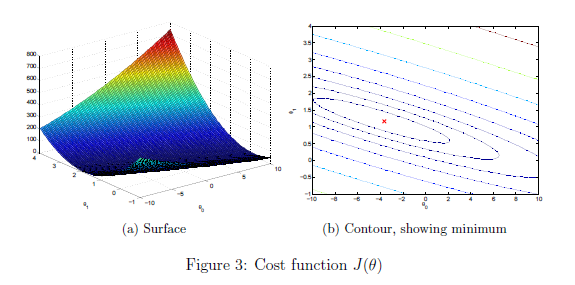

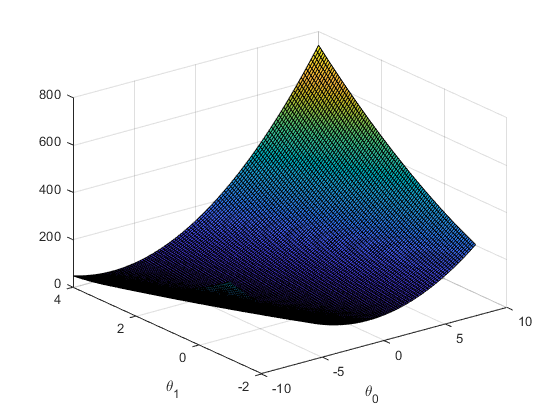

% Because of the way meshgrids work in the surf command, we need to
% transpose J_vals before calling surf, or else the axes will be flipped
J_vals = J_vals';

% Surface plot
figure;
surf(theta0_vals, theta1_vals, J_vals)
xlabel('\theta_0'); ylabel('\theta_1');

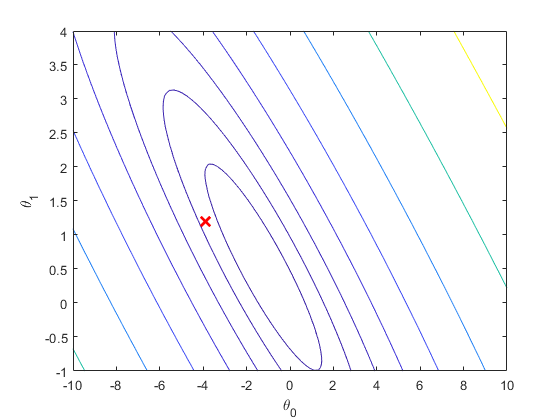


% Contour plot
figure;
% Plot J_vals as 15 contours spaced logarithmically between 0.01 and 100
contour(theta0_vals, theta1_vals, J_vals, logspace(-2, 3, 20))
xlabel('\theta_0'); ylabel('\theta_1');
hold on;
plot(theta(1), theta(2), 'rx', 'MarkerSize', 10, 'LineWidth', 2);
hold off;

    The purpose of these graphs is to show you that how $J(\theta)$ varies with changes in $\theta_0$ and $\theta_1$. The cost function $J(\theta)$ is bowl-shaped and has a global mininum. (This is easier to see in the contour plot than in the 3D surface plot). This minimum is the optimal point for $\theta_0$ and $\theta_1$, and each step of gradient descent moves closer to this point.

## Optional Exercises:

If you have successfully completed the material above, congratulations! You now understand linear regression and should able to start using it on your own datasets. For the rest of this programming exercise, we have included the following optional exercises. These exercises will help you gain a deeper understanding of the material, and if you are able to do so, we encourage you to complete them as well.

## 3. Linear regression with multiple variables

In this part, you will implement linear regression with multiple variables to predict the prices of houses. Suppose you are selling your house and you want to know what a good market price would be. One way to do this is to first collect information on recent houses sold and make a model of housing prices.

    The file `ex1data2.txt` contains a training set of housing prices in Portland, Oregon. The first column is the size of the house (in square feet), the second column is the number of bedrooms, and the third column is the price of the house. Run this section now to preview the data.

% Load Data
data = load('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Print out some data points
% First 10 examples from the dataset
fprintf(' x = [%.0f %.0f], y = %.0f \n', [X(1:10,:) y(1:10,:)]');

 x = [2104 3], y = 399900 
 x = [1600 3], y = 329900 
 x = [2400 3], y = 369000 
 x = [1416 2], y = 232000 
 x = [3000 4], y = 539900 
 x = [1985 4], y = 299900 
 x = [1534 3], y = 314900 
 x = [1427 3], y = 198999 
 x = [1380 3], y = 212000 
 x = [1494 3], y = 242500 


The remainder of this script has been set up to help you step through this exercise.

### 3.1 Feature Normalization

This section of the script will start by loading and displaying some values from this dataset. By looking at the values, note that house sizes are about 1000 times the number of bedrooms. When features differ by orders of magnitude, first performing feature scaling can make gradient descent converge much more quickly.

    Your task here is to complete the code in `featureNormalize.m` to:

- Subtract the mean value of each feature from the dataset.

- After subtracting the mean, additionally scale (divide) the feature values by their respective "standard deviations".

The standard deviation is a way of measuring how much variation there is in the range of values of a particular feature (most data points will lie within $\pm 2$ standard deviations of the mean); this is an alternative to taking the range of values (*max - min*). In MATLAB, you can use the `std` function to compute the standard deviation. For example, inside `featureNormalize.m`, the quantity `X(:,1)` contains all the values of $x_1$ (house sizes) in the training set, so `std(X(:,1))` computes the standard deviation of the house sizes. At the time that `featureNormalize.m` is called, the extra column of 1's corresponding to $x_0 = 1$ has not yet been added to `X` (see the code below for details).

    You will do this for all the features and your code should work with datasets of all sizes (any number of features / examples). Note that each column of the matrix `X` corresponds to one feature. When you are finished with `featureNormailize.m`, run this section to normailze the features of the housing dataset.

% Scale features and set them to zero mean
[X, mu, sigma] = featureNormalize(X);


mean(X_norm(:,1)): 0.000000
std(X_norm(:,1)): 1.000000
mean(X_norm(:,2)): 0.000000
std(X_norm(:,2)): 1.000000

**Implementation Note: **When normalizing the features, it is important to store the values used for normalization - the mean value and the standard deviation used for the computations. After learning the parameters from the model, we often want to predict the prices of houses we have not seen before. Given a new `x` value (living room area and number of bedrooms), we must first normalize `x` using the mean and standard deviation that we had previously computed from the training set.

#### Add the bias term

Now that we have normailzed the features, we again add a column of ones corresponding to $\theta_0$ to the data matrix `X``.`

% Add intercept term to X
X = [ones(m, 1) X];

### 3.2 Gradient Descent

Previously, you implemented gradient descent on a univariate regression problem. The only difference now is that there is one more feature in the matrix `X`. The hypothesis function and the batch gradient descent update rule remain unchanged.

    You should complete the code in `computeCostMulti.m` and `gradientDescentMulti``.m `to implement the cost function and gradient descent for linear regression *with multiple variables*. If your code in the previous part (single variable) already supports multiple variables, you can use it here too.

Make sure your code supports any number of features and is well-vectorized. You can use the command `size(X,2)` to find out how many features are present in the dataset.

    We have provided you with the following starter code below that runs gradient descent with a particular learning rate (`alpha`). Your task is to first make sure that your functions `computeCost` and `gradientDescent` already work with this starter code and support multiple variables.  

**Implementation Note: **In the multivariate case, the cost function can also be written in the following vectorized form:


$$J(\theta)=\frac{1}{2m}\left(X\theta-\vec{y}\right)^T\left(X\theta-\vec{y}\right)$$


where


$$X=\left\lbrack \begin{array}{c}
{-\;\left(x^{\left(1\right)} \right)}^T -\\
{-\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \;\\
{-\;\left(x^{\left(m\right)} \right)}^T -
\end{array}\right\rbrack \;\;\;\;\;\;\;\;\;\;\;\vec{y} =\left\lbrack \begin{array}{c}
y^{\left(1\right)} \\
y^{\left(2\right)} \\
\vdots \;\\
y^{\left(m\right)} 
\end{array}\right\rbrack$$


The vectorized version is efficient when you're working with numerical computing tools like MATLAB. If you are an expert with matrix operations, you can prove to yourself that the two forms are equivalent.

% Run gradient descent
% Choose some alpha value
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

**********
Debug purposes:
Theta computed from gradient descent:0.000000,0.000000

theta = 	1.0e+04 *

    3.4041
    1.0463
    0.5412



Iteration: 1 
Cost: 53294079419.249496
 ********************
Debug purposes:
Theta computed from gradient descent:34041.265957,10463.293377

theta = 	1.0e+04 *

    6.4678
    1.9606
    0.9722



Iteration: 2 
Cost: 43427073067.896156
 ********************
Debug purposes:
Theta computed from gradient descent:64678.405319,19605.893264

theta = 	1.0e+04 *

    9.2252
    2.7618
    1.3108



Iteration: 3 
Cost: 35499635425.210716
 ********************
Debug purposes:
Theta computed from gradient descent:92251.830745,27617.518321

theta = 	1.0e+05 *

    1.1707
    0.3466
    0.1572



Iteration: 4 
Cost: 29122571721.065815
 ********************
Debug purposes:
Theta computed from gradient descent:117067.913628,34659.434841

theta = 	1.0e+05 *

    1.3940
    0.4087
    0.1770



Iteration: 5 
Cost: 23986667348.856903
 ********************
Debug purposes:
Theta computed from gradient descent:139402.388222,40868.778680

theta = 	1.0e+05 *

    1.5950
    0.4636
    0.1914



Iteration: 6 
Cost: 19845773040.119987
 ********************
Debug purposes:
Theta computed from gradient descent:159503.415358,46362.218277

theta = 	1.0e+05 *

    1.7759
    0.5124
    0.2014



Iteration: 7 
Cost: 16503590007.117664
 ********************
Debug purposes:
Theta computed from gradient descent:177594.339779,51239.059322

theta = 	1.0e+05 *

    1.9388
    0.5558
    0.2077



Iteration: 8 
Cost: 13803314822.503111
 ********************
Debug purposes:
Theta computed from gradient descent:193876.171759,55583.876281

theta = 	1.0e+05 *

    2.0853
    0.5947
    0.2110



Iteration: 9 
Cost: 11619502166.181107
 ********************
Debug purposes:
Theta computed from gradient descent:208529.820540,59468.742985

theta = 	1.0e+05 *

    2.2172
    0.6296
    0.2119



Iteration: 10 
Cost: 9851653321.075933
 ********************
Debug purposes:
Theta computed from gradient descent:221718.104444,62955.123454

theta = 	1.0e+05 *

    2.3359
    0.6610
    0.2108



Iteration: 11 
Cost: 8419151757.715208
 ********************
Debug purposes:
Theta computed from gradient descent:233587.559957,66095.474797

theta = 	1.0e+05 *

    2.4427
    0.6893
    0.2081



Iteration: 12 
Cost: 7257253419.552914
 ********************
Debug purposes:
Theta computed from gradient descent:244270.069919,68934.606119

theta = 	1.0e+05 *

    2.5388
    0.7151
    0.2040



Iteration: 13 
Cost: 6313905159.886336
 ********************
Debug purposes:
Theta computed from gradient descent:253884.328884,71510.830652

theta = 	1.0e+05 *

    2.6254
    0.7386
    0.1990



Iteration: 14 
Cost: 5547215209.267678
 ********************
Debug purposes:
Theta computed from gradient descent:262537.161953,73856.942652

theta = 	1.0e+05 *

    2.7032
    0.7600
    0.1932



Iteration: 15 
Cost: 4923438315.939960
 ********************
Debug purposes:
Theta computed from gradient descent:270324.711715,76001.045783

theta = 	1.0e+05 *

    2.7733
    0.7797
    0.1867



Iteration: 16 
Cost: 4415368104.849248
 ********************
Debug purposes:
Theta computed from gradient descent:277333.506501,77967.255643

theta = 	1.0e+05 *

    2.8364
    0.7978
    0.1799



Iteration: 17 
Cost: 4001052348.560945
 ********************
Debug purposes:
Theta computed from gradient descent:283641.421809,79776.295613

theta = 	1.0e+05 *

    2.8932
    0.8145
    0.1727



Iteration: 18 
Cost: 3662764822.297399
 ********************
Debug purposes:
Theta computed from gradient descent:289318.545585,81446.002299

theta = 	1.0e+05 *

    2.9443
    0.8299
    0.1652



Iteration: 19 
Cost: 3386181424.843304
 ********************
Debug purposes:
Theta computed from gradient descent:294427.956984,82991.754334

theta = 	1.0e+05 *

    2.9903
    0.8443
    0.1577



Iteration: 20 
Cost: 3159719197.521465
 ********************
Debug purposes:
Theta computed from gradient descent:299026.427243,84426.836236

theta = 	1.0e+05 *

    3.0317
    0.8576
    0.1501



Iteration: 21 
Cost: 2974005458.123918
 ********************
Debug purposes:
Theta computed from gradient descent:303165.050476,85762.747198

theta = 	1.0e+05 *

    3.0689
    0.8701
    0.1426



Iteration: 22 
Cost: 2821451015.551958
 ********************
Debug purposes:
Theta computed from gradient descent:306889.811386,87009.463204

theta = 	1.0e+05 *

    3.1024
    0.8818
    0.1350



Iteration: 23 
Cost: 2695906750.544815
 ********************
Debug purposes:
Theta computed from gradient descent:310242.096205,88175.659576

theta = 	1.0e+05 *

    3.1326
    0.8927
    0.1276



Iteration: 24 
Cost: 2592387051.287718
 ********************
Debug purposes:
Theta computed from gradient descent:313259.152542,89268.899982

theta = 	1.0e+05 *

    3.1597
    0.9030
    0.1203



Iteration: 25 
Cost: 2506846921.739851
 ********************
Debug purposes:
Theta computed from gradient descent:315974.503245,90295.796986

theta = 	1.0e+05 *

    3.1842
    0.9126
    0.1132



Iteration: 26 
Cost: 2436002222.713760
 ********************
Debug purposes:
Theta computed from gradient descent:318418.318878,91262.148492

theta = 	1.0e+05 *

    3.2062
    0.9217
    0.1062



Iteration: 27 
Cost: 2377184606.916689
 ********************
Debug purposes:
Theta computed from gradient descent:320617.752948,92173.053727

theta = 	1.0e+05 *

    3.2260
    0.9303
    0.0994



Iteration: 28 
Cost: 2328224383.138514
 ********************
Debug purposes:
Theta computed from gradient descent:322597.243610,93033.011881

theta = 	1.0e+05 *

    3.2438
    0.9385
    0.0928



Iteration: 29 
Cost: 2287355880.615621
 ********************
Debug purposes:
Theta computed from gradient descent:324378.785207,93846.006032

theta = 	1.0e+05 *

    3.2598
    0.9462
    0.0864



Iteration: 30 
Cost: 2253140952.235452
 ********************
Debug purposes:
Theta computed from gradient descent:325982.172644,94615.574586

theta = 	1.0e+05 *

    3.2743
    0.9534
    0.0803



Iteration: 31 
Cost: 2224407109.705773
 ********************
Debug purposes:
Theta computed from gradient descent:327425.221337,95344.872134

theta = 	1.0e+05 *

    3.2872
    0.9604
    0.0743



Iteration: 32 
Cost: 2200197468.522927
 ********************
Debug purposes:
Theta computed from gradient descent:328723.965160,96036.721308

theta = 	1.0e+05 *

    3.2989
    0.9669
    0.0685



Iteration: 33 
Cost: 2179730229.884958
 ********************
Debug purposes:
Theta computed from gradient descent:329892.834602,96693.657025

theta = 	1.0e+05 *

    3.3094
    0.9732
    0.0629



Iteration: 34 
Cost: 2162365867.839530
 ********************
Debug purposes:
Theta computed from gradient descent:330944.817099,97317.964242

theta = 	1.0e+05 *

    3.3189
    0.9791
    0.0575



Iteration: 35 
Cost: 2147580544.564920
 ********************
Debug purposes:
Theta computed from gradient descent:331891.601347,97911.710215

theta = 	1.0e+05 *

    3.3274
    0.9848
    0.0524



Iteration: 36 
Cost: 2134944561.971616
 ********************
Debug purposes:
Theta computed from gradient descent:332743.707169,98476.772092

theta = 	1.0e+05 *

    3.3351
    0.9901
    0.0474



Iteration: 37 
Cost: 2124104887.508007
 ********************
Debug purposes:
Theta computed from gradient descent:333510.602410,99014.860530

theta = 	1.0e+05 *

    3.3420
    0.9953
    0.0426



Iteration: 38 
Cost: 2114770977.117747
 ********************
Debug purposes:
Theta computed from gradient descent:334200.808126,99527.539944

theta = 	1.0e+05 *

    3.3482
    1.0002
    0.0380



Iteration: 39 
Cost: 2106703267.493427
 ********************
Debug purposes:
Theta computed from gradient descent:334821.993271,100016.245882

theta = 	1.0e+05 *

    3.3538
    1.0048
    0.0336



Iteration: 40 
Cost: 2099703830.120800
 ********************
Debug purposes:
Theta computed from gradient descent:335381.059902,100482.299966

theta = 	1.0e+05 *

    3.3588
    1.0093
    0.0294



Iteration: 41 
Cost: 2093608776.736805
 ********************
Debug purposes:
Theta computed from gradient descent:335884.219869,100926.922750

theta = 	1.0e+05 *

    3.3634
    1.0135
    0.0253



Iteration: 42 
Cost: 2088282084.249810
 ********************
Debug purposes:
Theta computed from gradient descent:336337.063839,101351.244819

theta = 	1.0e+05 *

    3.3674
    1.0176
    0.0214



Iteration: 43 
Cost: 2083610570.520020
 ********************
Debug purposes:
Theta computed from gradient descent:336744.623413,101756.316368

theta = 	1.0e+05 *

    3.3711
    1.0214
    0.0177



Iteration: 44 
Cost: 2079499803.589591
 ********************
Debug purposes:
Theta computed from gradient descent:337111.427029,102143.115507

theta = 	1.0e+05 *

    3.3744
    1.0251
    0.0141



Iteration: 45 
Cost: 2075870768.333605
 ********************
Debug purposes:
Theta computed from gradient descent:337441.550284,102512.555467

theta = 	1.0e+05 *

    3.3774
    1.0287
    0.0107



Iteration: 46 
Cost: 2072657147.965326
 ********************
Debug purposes:
Theta computed from gradient descent:337738.661213,102865.490866

theta = 	1.0e+05 *

    3.3801
    1.0320
    0.0074



Iteration: 47 
Cost: 2069803104.895973
 ********************
Debug purposes:
Theta computed from gradient descent:338006.061049,103202.723178

theta = 	1.0e+05 *

    3.3825
    1.0353
    0.0042



Iteration: 48 
Cost: 2067261467.349069
 ********************
Debug purposes:
Theta computed from gradient descent:338246.720901,103525.005516

theta = 	1.0e+05 *

    3.3846
    1.0383
    0.0012



Iteration: 49 
Cost: 2064992245.853307
 ********************
Debug purposes:
Theta computed from gradient descent:338463.314769,103833.046830

theta = 	1.0e+05 *

    3.3866
    1.0413
   -0.0017



Iteration: 50 
Cost: 2062961418.085969
 ********************
Debug purposes:
Theta computed from gradient descent:338658.249249,104127.515597

theta = 3×1
    3.3883
    1.0441
   -0.0045



Iteration: 51 
Cost: 2061139932.156912
 ********************
Debug purposes:
Theta computed from gradient descent:338833.690282,104409.043084

theta = 3×1
    3.3899
    1.0468
   -0.0072



Iteration: 52 
Cost: 2059502887.832942
 ********************
Debug purposes:
Theta computed from gradient descent:338991.587211,104678.226237

theta = 3×1
    3.3913
    1.0494
   -0.0097



Iteration: 53 
Cost: 2058028862.825486
 ********************
Debug purposes:
Theta computed from gradient descent:339133.694447,104935.630243

theta = 3×1
    3.3926
    1.0518
   -0.0121



Iteration: 54 
Cost: 2056699357.441691
 ********************
Debug purposes:
Theta computed from gradient descent:339261.590960,105181.790829

theta = 3×1
    3.3938
    1.0542
   -0.0145



Iteration: 55 
Cost: 2055498335.905919
 ********************
Debug purposes:
Theta computed from gradient descent:339376.697822,105417.216307

theta = 3×1
    3.3948
    1.0564
   -0.0167



Iteration: 56 
Cost: 2054411846.717885
 ********************
Debug purposes:
Theta computed from gradient descent:339480.293997,105642.389419

theta = 3×1
    3.3957
    1.0586
   -0.0188



Iteration: 57 
Cost: 2053427707.705581
 ********************
Debug purposes:
Theta computed from gradient descent:339573.530555,105857.769000

theta = 3×1
    3.3966
    1.0606
   -0.0209



Iteration: 58 
Cost: 2052535244.101682
 ********************
Debug purposes:
Theta computed from gradient descent:339657.443457,106063.791485

theta = 3×1
    3.3973
    1.0626
   -0.0229



Iteration: 59 
Cost: 2051725070.139004
 ********************
Debug purposes:
Theta computed from gradient descent:339732.965068,106260.872274

theta = 3×1
    3.3980
    1.0645
   -0.0247



Iteration: 60 
Cost: 2050988906.419711
 ********************
Debug purposes:
Theta computed from gradient descent:339800.934519,106449.406981

theta = 3×1
    3.3986
    1.0663
   -0.0265



Iteration: 61 
Cost: 2050319426.741300
 ********************
Debug purposes:
Theta computed from gradient descent:339862.107025,106629.772578

theta = 3×1
    3.3992
    1.0680
   -0.0282



Iteration: 62 
Cost: 2049710129.222830
 ********************
Debug purposes:
Theta computed from gradient descent:339917.162280,106802.328437

theta = 3×1
    3.3997
    1.0697
   -0.0299



Iteration: 63 
Cost: 2049155227.517967
 ********************
Debug purposes:
Theta computed from gradient descent:339966.712009,106967.417301

theta = 3×1
    3.4001
    1.0713
   -0.0315



Iteration: 64 
Cost: 2048649558.668266
 ********************
Debug purposes:
Theta computed from gradient descent:340011.306766,107125.366177

theta = 3×1
    3.4005
    1.0728
   -0.0330



Iteration: 65 
Cost: 2048188504.774017
 ********************
Debug purposes:
Theta computed from gradient descent:340051.442046,107276.487158

theta = 3×1
    3.4009
    1.0742
   -0.0344



Iteration: 66 
Cost: 2047767926.167908
 ********************
Debug purposes:
Theta computed from gradient descent:340087.563799,107421.078195

theta = 3×1
    3.4012
    1.0756
   -0.0358



Iteration: 67 
Cost: 2047384104.190503
 ********************
Debug purposes:
Theta computed from gradient descent:340120.073377,107559.423812

theta = 3×1
    3.4015
    1.0769
   -0.0371



Iteration: 68 
Cost: 2047033692.003824
 ********************
Debug purposes:
Theta computed from gradient descent:340149.331997,107691.795778

theta = 3×1
    3.4018
    1.0782
   -0.0384



Iteration: 69 
Cost: 2046713672.154528
 ********************
Debug purposes:
Theta computed from gradient descent:340175.664754,107818.453728

theta = 3×1
    3.4020
    1.0794
   -0.0396



Iteration: 70 
Cost: 2046421319.822910
 ********************
Debug purposes:
Theta computed from gradient descent:340199.364236,107939.645757

theta = 3×1
    3.4022
    1.0806
   -0.0407



Iteration: 71 
Cost: 2046154170.877711
 ********************
Debug purposes:
Theta computed from gradient descent:340220.693770,108055.608964

theta = 3×1
    3.4024
    1.0817
   -0.0419



Iteration: 72 
Cost: 2045909994.007006
 ********************
Debug purposes:
Theta computed from gradient descent:340239.890351,108166.569982

theta = 3×1
    3.4026
    1.0827
   -0.0429



Iteration: 73 
Cost: 2045686766.318711
 ********************
Debug purposes:
Theta computed from gradient descent:340257.167273,108272.745461

theta = 3×1
    3.4027
    1.0837
   -0.0439



Iteration: 74 
Cost: 2045482651.905279
 ********************
Debug purposes:
Theta computed from gradient descent:340272.716503,108374.342534

theta = 3×1
    3.4029
    1.0847
   -0.0449



Iteration: 75 
Cost: 2045295982.950281
 ********************
Debug purposes:
Theta computed from gradient descent:340286.710810,108471.559257

theta = 3×1
    3.4030
    1.0856
   -0.0458



Iteration: 76 
Cost: 2045125243.022902
 ********************
Debug purposes:
Theta computed from gradient descent:340299.305687,108564.585021

theta = 3×1
    3.4031
    1.0865
   -0.0467



Iteration: 77 
Cost: 2044969052.262787
 ********************
Debug purposes:
Theta computed from gradient descent:340310.641075,108653.600947

theta = 3×1
    3.4032
    1.0874
   -0.0476



Iteration: 78 
Cost: 2044826154.204241
 ********************
Debug purposes:
Theta computed from gradient descent:340320.842925,108738.780262

theta = 3×1
    3.4033
    1.0882
   -0.0484



Iteration: 79 
Cost: 2044695404.027398
 ********************
Debug purposes:
Theta computed from gradient descent:340330.024590,108820.288647

theta = 3×1
    3.4034
    1.0890
   -0.0492



Iteration: 80 
Cost: 2044575758.055917
 ********************
Debug purposes:
Theta computed from gradient descent:340338.288089,108898.284583

theta = 3×1
    3.4035
    1.0897
   -0.0499



Iteration: 81 
Cost: 2044466264.347464
 ********************
Debug purposes:
Theta computed from gradient descent:340345.725237,108972.919664

theta = 3×1
    3.4035
    1.0904
   -0.0506



Iteration: 82 
Cost: 2044366054.245428
 ********************
Debug purposes:
Theta computed from gradient descent:340352.418671,109044.338908

theta = 3×1
    3.4036
    1.0911
   -0.0513



Iteration: 83 
Cost: 2044274334.778870
 ********************
Debug purposes:
Theta computed from gradient descent:340358.442761,109112.681043

theta = 3×1
    3.4036
    1.0918
   -0.0520



Iteration: 84 
Cost: 2044190381.813363
 ********************
Debug purposes:
Theta computed from gradient descent:340363.864443,109178.078790

theta = 3×1
    3.4037
    1.0924
   -0.0526



Iteration: 85 
Cost: 2044113533.868455
 ********************
Debug purposes:
Theta computed from gradient descent:340368.743956,109240.659122

theta = 3×1
    3.4037
    1.0930
   -0.0532



Iteration: 86 
Cost: 2044043186.528587
 ********************
Debug purposes:
Theta computed from gradient descent:340373.135518,109300.543517

theta = 3×1
    3.4038
    1.0936
   -0.0538



Iteration: 87 
Cost: 2043978787.383710
 ********************
Debug purposes:
Theta computed from gradient descent:340377.087923,109357.848202

theta = 3×1
    3.4038
    1.0941
   -0.0543



Iteration: 88 
Cost: 2043919831.443787
 ********************
Debug purposes:
Theta computed from gradient descent:340380.645088,109412.684380

theta = 3×1
    3.4038
    1.0947
   -0.0548



Iteration: 89 
Cost: 2043865856.978248
 ********************
Debug purposes:
Theta computed from gradient descent:340383.846537,109465.158447

theta = 3×1
    3.4039
    1.0952
   -0.0553



Iteration: 90 
Cost: 2043816441.737255
 ********************
Debug purposes:
Theta computed from gradient descent:340386.727841,109515.372206

theta = 3×1
    3.4039
    1.0956
   -0.0558



Iteration: 91 
Cost: 2043771199.516671
 ********************
Debug purposes:
Theta computed from gradient descent:340389.321014,109563.423064

theta = 3×1
    3.4039
    1.0961
   -0.0563



Iteration: 92 
Cost: 2043729777.032990
 ********************
Debug purposes:
Theta computed from gradient descent:340391.654870,109609.404223

theta = 3×1
    3.4039
    1.0965
   -0.0567



Iteration: 93 
Cost: 2043691851.078198
 ********************
Debug purposes:
Theta computed from gradient descent:340393.755341,109653.404863

theta = 3×1
    3.4040
    1.0970
   -0.0571



Iteration: 94 
Cost: 2043657125.927846
 ********************
Debug purposes:
Theta computed from gradient descent:340395.645764,109695.510316

theta = 3×1
    3.4040
    1.0974
   -0.0575



Iteration: 95 
Cost: 2043625330.978421
 ********************
Debug purposes:
Theta computed from gradient descent:340397.347145,109735.802235

theta = 3×1
    3.4040
    1.0977
   -0.0579



Iteration: 96 
Cost: 2043596218.592659
 ********************
Debug purposes:
Theta computed from gradient descent:340398.878388,109774.358751

theta = 3×1
    3.4040
    1.0981
   -0.0583



Iteration: 97 
Cost: 2043569562.133560
 ********************
Debug purposes:
Theta computed from gradient descent:340400.256507,109811.254624

theta = 3×1
    3.4040
    1.0985
   -0.0586



Iteration: 98 
Cost: 2043545154.169892
 ********************
Debug purposes:
Theta computed from gradient descent:340401.496813,109846.561394

theta = 3×1
    3.4040
    1.0988
   -0.0590



Iteration: 99 
Cost: 2043522804.837592
 ********************
Debug purposes:
Theta computed from gradient descent:340402.613090,109880.347514

theta = 3×1
    3.4040
    1.0991
   -0.0593



Iteration: 100 
Cost: 2043502340.343070
 ********************
Debug purposes:
Theta computed from gradient descent:340403.617738,109912.678489

theta = 3×1
    3.4040
    1.0994
   -0.0596



Iteration: 101 
Cost: 2043483601.595718
 ********************
Debug purposes:
Theta computed from gradient descent:340404.521922,109943.616999

theta = 3×1
    3.4041
    1.0997
   -0.0599



Iteration: 102 
Cost: 2043466442.958151
 ********************
Debug purposes:
Theta computed from gradient descent:340405.335687,109973.223023

theta = 3×1
    3.4041
    1.1000
   -0.0602



Iteration: 103 
Cost: 2043450731.103799
 ********************
Debug purposes:
Theta computed from gradient descent:340406.068076,110001.553957

theta = 3×1
    3.4041
    1.1003
   -0.0605



Iteration: 104 
Cost: 2043436343.972404
 ********************
Debug purposes:
Theta computed from gradient descent:340406.727226,110028.664721

theta = 3×1
    3.4041
    1.1005
   -0.0607



Iteration: 105 
Cost: 2043423169.814873
 ********************
Debug purposes:
Theta computed from gradient descent:340407.320460,110054.607871

theta = 3×1
    3.4041
    1.1008
   -0.0610



Iteration: 106 
Cost: 2043411106.319697
 ********************
Debug purposes:
Theta computed from gradient descent:340407.854372,110079.433698

theta = 3×1
    3.4041
    1.1010
   -0.0612



Iteration: 107 
Cost: 2043400059.813861
 ********************
Debug purposes:
Theta computed from gradient descent:340408.334892,110103.190325

theta = 3×1
    3.4041
    1.1013
   -0.0614



Iteration: 108 
Cost: 2043389944.531810
 ********************
Debug purposes:
Theta computed from gradient descent:340408.767360,110125.923805

theta = 3×1
    3.4041
    1.1015
   -0.0617



Iteration: 109 
Cost: 2043380681.946586
 ********************
Debug purposes:
Theta computed from gradient descent:340409.156582,110147.678203

theta = 3×1
    3.4041
    1.1017
   -0.0619



Iteration: 110 
Cost: 2043372200.157797
 ********************
Debug purposes:
Theta computed from gradient descent:340409.506881,110168.495690

theta = 3×1
    3.4041
    1.1019
   -0.0621



Iteration: 111 
Cost: 2043364433.331552
 ********************
Debug purposes:
Theta computed from gradient descent:340409.822150,110188.416616

theta = 3×1
    3.4041
    1.1021
   -0.0623



Iteration: 112 
Cost: 2043357321.187886
 ********************
Debug purposes:
Theta computed from gradient descent:340410.105893,110207.479596

theta = 3×1
    3.4041
    1.1023
   -0.0624



Iteration: 113 
Cost: 2043350808.531633
 ********************
Debug purposes:
Theta computed from gradient descent:340410.361261,110225.721581

theta = 3×1
    3.4041
    1.1024
   -0.0626



Iteration: 114 
Cost: 2043344844.823049
 ********************
Debug purposes:
Theta computed from gradient descent:340410.591092,110243.177930

theta = 3×1
    3.4041
    1.1026
   -0.0628



Iteration: 115 
Cost: 2043339383.784755
 ********************
Debug purposes:
Theta computed from gradient descent:340410.797941,110259.882480

theta = 3×1
    3.4041
    1.1028
   -0.0629



Iteration: 116 
Cost: 2043334383.041968
 ********************
Debug purposes:
Theta computed from gradient descent:340410.984104,110275.867609

theta = 3×1
    3.4041
    1.1029
   -0.0631



Iteration: 117 
Cost: 2043329803.793139
 ********************
Debug purposes:
Theta computed from gradient descent:340411.151651,110291.164300

theta = 3×1
    3.4041
    1.1031
   -0.0632



Iteration: 118 
Cost: 2043325610.508430
 ********************
Debug purposes:
Theta computed from gradient descent:340411.302443,110305.802205

theta = 3×1
    3.4041
    1.1032
   -0.0634



Iteration: 119 
Cost: 2043321770.653697
 ********************
Debug purposes:
Theta computed from gradient descent:340411.438156,110319.809695

theta = 3×1
    3.4041
    1.1033
   -0.0635



Iteration: 120 
Cost: 2043318254.437768
 ********************
Debug purposes:
Theta computed from gradient descent:340411.560298,110333.213921

theta = 3×1
    3.4041
    1.1035
   -0.0636



Iteration: 121 
Cost: 2043315034.581071
 ********************
Debug purposes:
Theta computed from gradient descent:340411.670226,110346.040865

theta = 3×1
    3.4041
    1.1036
   -0.0638



Iteration: 122 
Cost: 2043312086.103811
 ********************
Debug purposes:
Theta computed from gradient descent:340411.769161,110358.315388

theta = 3×1
    3.4041
    1.1037
   -0.0639



Iteration: 123 
Cost: 2043309386.132006
 ********************
Debug purposes:
Theta computed from gradient descent:340411.858202,110370.061281

theta = 3×1
    3.4041
    1.1038
   -0.0640



Iteration: 124 
Cost: 2043306913.719924
 ********************
Debug purposes:
Theta computed from gradient descent:340411.938339,110381.301313

theta = 3×1
    3.4041
    1.1039
   -0.0641



Iteration: 125 
Cost: 2043304649.687474
 ********************
Debug purposes:
Theta computed from gradient descent:340412.010463,110392.057268

theta = 3×1
    3.4041
    1.1040
   -0.0642



Iteration: 126 
Cost: 2043302576.471339
 ********************
Debug purposes:
Theta computed from gradient descent:340412.075374,110402.349996

theta = 3×1
    3.4041
    1.1041
   -0.0643



Iteration: 127 
Cost: 2043300677.988660
 ********************
Debug purposes:
Theta computed from gradient descent:340412.133794,110412.199445

theta = 3×1
    3.4041
    1.1042
   -0.0644



Iteration: 128 
Cost: 2043298939.512217
 ********************
Debug purposes:
Theta computed from gradient descent:340412.186372,110421.624706

theta = 3×1
    3.4041
    1.1043
   -0.0645



Iteration: 129 
Cost: 2043297347.556145
 ********************
Debug purposes:
Theta computed from gradient descent:340412.233692,110430.644049

theta = 3×1
    3.4041
    1.1044
   -0.0646



Iteration: 130 
Cost: 2043295889.771280
 ********************
Debug purposes:
Theta computed from gradient descent:340412.276281,110439.274955

theta = 3×1
    3.4041
    1.1045
   -0.0647



Iteration: 131 
Cost: 2043294554.849337
 ********************
Debug purposes:
Theta computed from gradient descent:340412.314610,110447.534153

theta = 3×1
    3.4041
    1.1046
   -0.0647



Iteration: 132 
Cost: 2043293332.435170
 ********************
Debug purposes:
Theta computed from gradient descent:340412.349106,110455.437652

theta = 3×1
    3.4041
    1.1046
   -0.0648



Iteration: 133 
Cost: 2043292213.046420
 ********************
Debug purposes:
Theta computed from gradient descent:340412.380153,110463.000769

theta = 3×1
    3.4041
    1.1047
   -0.0649



Iteration: 134 
Cost: 2043291187.999948
 ********************
Debug purposes:
Theta computed from gradient descent:340412.408095,110470.238166

theta = 3×1
    3.4041
    1.1048
   -0.0650



Iteration: 135 
Cost: 2043290249.344469
 ********************
Debug purposes:
Theta computed from gradient descent:340412.433243,110477.163869

theta = 3×1
    3.4041
    1.1048
   -0.0650



Iteration: 136 
Cost: 2043289389.798860
 ********************
Debug purposes:
Theta computed from gradient descent:340412.455876,110483.791302

theta = 3×1
    3.4041
    1.1049
   -0.0651



Iteration: 137 
Cost: 2043288602.695676
 ********************
Debug purposes:
Theta computed from gradient descent:340412.476246,110490.133311

theta = 3×1
    3.4041
    1.1050
   -0.0651



Iteration: 138 
Cost: 2043287881.929421
 ********************
Debug purposes:
Theta computed from gradient descent:340412.494579,110496.202189

theta = 3×1
    3.4041
    1.1050
   -0.0652



Iteration: 139 
Cost: 2043287221.909186
 ********************
Debug purposes:
Theta computed from gradient descent:340412.511079,110502.009697

theta = 3×1
    3.4041
    1.1051
   -0.0653



Iteration: 140 
Cost: 2043286617.515275
 ********************
Debug purposes:
Theta computed from gradient descent:340412.525928,110507.567094

theta = 3×1
    3.4041
    1.1051
   -0.0653



Iteration: 141 
Cost: 2043286064.059486
 ********************
Debug purposes:
Theta computed from gradient descent:340412.539293,110512.885149

theta = 3×1
    3.4041
    1.1052
   -0.0654



Iteration: 142 
Cost: 2043285557.248747
 ********************
Debug purposes:
Theta computed from gradient descent:340412.551321,110517.974172

theta = 3×1
    3.4041
    1.1052
   -0.0654



Iteration: 143 
Cost: 2043285093.151814
 ********************
Debug purposes:
Theta computed from gradient descent:340412.562146,110522.844026

theta = 3×1
    3.4041
    1.1053
   -0.0655



Iteration: 144 
Cost: 2043284668.168767
 ********************
Debug purposes:
Theta computed from gradient descent:340412.571889,110527.504149

theta = 3×1
    3.4041
    1.1053
   -0.0655



Iteration: 145 
Cost: 2043284279.003092
 ********************
Debug purposes:
Theta computed from gradient descent:340412.580658,110531.963574

theta = 3×1
    3.4041
    1.1054
   -0.0655



Iteration: 146 
Cost: 2043283922.636110
 ********************
Debug purposes:
Theta computed from gradient descent:340412.588549,110536.230946

theta = 3×1
    3.4041
    1.1054
   -0.0656



Iteration: 147 
Cost: 2043283596.303553
 ********************
Debug purposes:
Theta computed from gradient descent:340412.595652,110540.314534

theta = 3×1
    3.4041
    1.1054
   -0.0656



Iteration: 148 
Cost: 2043283297.474128
 ********************
Debug purposes:
Theta computed from gradient descent:340412.602044,110544.222254

theta = 3×1
    3.4041
    1.1055
   -0.0657



Iteration: 149 
Cost: 2043283023.829884
 ********************
Debug purposes:
Theta computed from gradient descent:340412.607797,110547.961680

theta = 3×1
    3.4041
    1.1055
   -0.0657



Iteration: 150 
Cost: 2043282773.248219
 ********************
Debug purposes:
Theta computed from gradient descent:340412.612975,110551.540060

theta = 3×1
    3.4041
    1.1055
   -0.0657



Iteration: 151 
Cost: 2043282543.785431
 ********************
Debug purposes:
Theta computed from gradient descent:340412.617635,110554.964330

theta = 3×1
    3.4041
    1.1056
   -0.0658



Iteration: 152 
Cost: 2043282333.661631
 ********************
Debug purposes:
Theta computed from gradient descent:340412.621829,110558.241127

theta = 3×1
    3.4041
    1.1056
   -0.0658



Iteration: 153 
Cost: 2043282141.246937
 ********************
Debug purposes:
Theta computed from gradient descent:340412.625603,110561.376801

theta = 3×1
    3.4041
    1.1056
   -0.0658



Iteration: 154 
Cost: 2043281965.048834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.629000,110564.377432

theta = 3×1
    3.4041
    1.1057
   -0.0659



Iteration: 155 
Cost: 2043281803.700598
 ********************
Debug purposes:
Theta computed from gradient descent:340412.632058,110567.248834

theta = 3×1
    3.4041
    1.1057
   -0.0659



Iteration: 156 
Cost: 2043281655.950690
 ********************
Debug purposes:
Theta computed from gradient descent:340412.634810,110569.996573

theta = 3×1
    3.4041
    1.1057
   -0.0659



Iteration: 157 
Cost: 2043281520.653048
 ********************
Debug purposes:
Theta computed from gradient descent:340412.637286,110572.625976

theta = 3×1
    3.4041
    1.1058
   -0.0659



Iteration: 158 
Cost: 2043281396.758205
 ********************
Debug purposes:
Theta computed from gradient descent:340412.639515,110575.142137

theta = 3×1
    3.4041
    1.1058
   -0.0660



Iteration: 159 
Cost: 2043281283.305138
 ********************
Debug purposes:
Theta computed from gradient descent:340412.641521,110577.549936

theta = 3×1
    3.4041
    1.1058
   -0.0660



Iteration: 160 
Cost: 2043281179.413821
 ********************
Debug purposes:
Theta computed from gradient descent:340412.643326,110579.854037

theta = 3×1
    3.4041
    1.1058
   -0.0660



Iteration: 161 
Cost: 2043281084.278397
 ********************
Debug purposes:
Theta computed from gradient descent:340412.644951,110582.058908

theta = 3×1
    3.4041
    1.1058
   -0.0660



Iteration: 162 
Cost: 2043280997.160921
 ********************
Debug purposes:
Theta computed from gradient descent:340412.646413,110584.168821

theta = 3×1
    3.4041
    1.1059
   -0.0660



Iteration: 163 
Cost: 2043280917.385651
 ********************
Debug purposes:
Theta computed from gradient descent:340412.647729,110586.187867

theta = 3×1
    3.4041
    1.1059
   -0.0661



Iteration: 164 
Cost: 2043280844.333787
 ********************
Debug purposes:
Theta computed from gradient descent:340412.648914,110588.119958

theta = 3×1
    3.4041
    1.1059
   -0.0661



Iteration: 165 
Cost: 2043280777.438684
 ********************
Debug purposes:
Theta computed from gradient descent:340412.649980,110589.968840

theta = 3×1
    3.4041
    1.1059
   -0.0661



Iteration: 166 
Cost: 2043280716.181455
 ********************
Debug purposes:
Theta computed from gradient descent:340412.650939,110591.738096

theta = 3×1
    3.4041
    1.1059
   -0.0661



Iteration: 167 
Cost: 2043280660.086944
 ********************
Debug purposes:
Theta computed from gradient descent:340412.651803,110593.431155

theta = 3×1
    3.4041
    1.1060
   -0.0661



Iteration: 168 
Cost: 2043280608.720041
 ********************
Debug purposes:
Theta computed from gradient descent:340412.652580,110595.051299

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 169 
Cost: 2043280561.682305
 ********************
Debug purposes:
Theta computed from gradient descent:340412.653280,110596.601669

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 170 
Cost: 2043280518.608877
 ********************
Debug purposes:
Theta computed from gradient descent:340412.653909,110598.085268

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 171 
Cost: 2043280479.165650
 ********************
Debug purposes:
Theta computed from gradient descent:340412.654476,110599.504974

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 172 
Cost: 2043280443.046669
 ********************
Debug purposes:
Theta computed from gradient descent:340412.654985,110600.863537

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 173 
Cost: 2043280409.971772
 ********************
Debug purposes:
Theta computed from gradient descent:340412.655444,110602.163590

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 174 
Cost: 2043280379.684405
 ********************
Debug purposes:
Theta computed from gradient descent:340412.655857,110603.407655

theta = 3×1
    3.4041
    1.1060
   -0.0662



Iteration: 175 
Cost: 2043280351.949636
 ********************
Debug purposes:
Theta computed from gradient descent:340412.656229,110604.598141

theta = 3×1
    3.4041
    1.1061
   -0.0662



Iteration: 176 
Cost: 2043280326.552334
 ********************
Debug purposes:
Theta computed from gradient descent:340412.656564,110605.737356

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 177 
Cost: 2043280303.295500
 ********************
Debug purposes:
Theta computed from gradient descent:340412.656865,110606.827509

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 178 
Cost: 2043280281.998736
 ********************
Debug purposes:
Theta computed from gradient descent:340412.657136,110607.870712

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 179 
Cost: 2043280262.496849
 ********************
Debug purposes:
Theta computed from gradient descent:340412.657380,110608.868987

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 180 
Cost: 2043280244.638567
 ********************
Debug purposes:
Theta computed from gradient descent:340412.657599,110609.824269

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 181 
Cost: 2043280228.285368
 ********************
Debug purposes:
Theta computed from gradient descent:340412.657797,110610.738411

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 182 
Cost: 2043280213.310407
 ********************
Debug purposes:
Theta computed from gradient descent:340412.657974,110611.613183

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 183 
Cost: 2043280199.597524
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658134,110612.450281

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 184 
Cost: 2043280187.040354
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658278,110613.251328

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 185 
Cost: 2043280175.541493
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658408,110614.017876

theta = 3×1
    3.4041
    1.1061
   -0.0663



Iteration: 186 
Cost: 2043280165.011749
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658525,110614.751411

theta = 3×1
    3.4041
    1.1062
   -0.0663



Iteration: 187 
Cost: 2043280155.369445
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658630,110615.453355

theta = 3×1
    3.4041
    1.1062
   -0.0663



Iteration: 188 
Cost: 2043280146.539787
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658724,110616.125068

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 189 
Cost: 2043280138.454286
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658809,110616.767853

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 190 
Cost: 2043280131.050225
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658886,110617.382955

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 191 
Cost: 2043280124.270174
 ********************
Debug purposes:
Theta computed from gradient descent:340412.658955,110617.971566

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 192 
Cost: 2043280118.061541
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659017,110618.534828

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 193 
Cost: 2043280112.376168
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659072,110619.073831

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 194 
Cost: 2043280107.169954
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659123,110619.589621

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 195 
Cost: 2043280102.402515
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659168,110620.083198

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 196 
Cost: 2043280098.036873
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659208,110620.555517

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 197 
Cost: 2043280094.039165
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659245,110621.007496

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 198 
Cost: 2043280090.378379
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659278,110621.440009

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 199 
Cost: 2043280087.026124
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659308,110621.853895

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 200 
Cost: 2043280083.956394
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659334,110622.249956

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 201 
Cost: 2043280081.145380
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659358,110622.628959

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 202 
Cost: 2043280078.571274
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659380,110622.991641

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 203 
Cost: 2043280076.214112
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659399,110623.338702

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 204 
Cost: 2043280074.055611
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659417,110623.670817

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 205 
Cost: 2043280072.079026
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659433,110623.988629

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 206 
Cost: 2043280070.269028
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659447,110624.292753

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 207 
Cost: 2043280068.611574
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659460,110624.583780

theta = 3×1
    3.4041
    1.1062
   -0.0664



Iteration: 208 
Cost: 2043280067.093809
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659471,110624.862273

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 209 
Cost: 2043280065.703960
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659481,110625.128772

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 210 
Cost: 2043280064.431247
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659491,110625.383794

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 211 
Cost: 2043280063.265797
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659499,110625.627832

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 212 
Cost: 2043280062.198572
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659507,110625.861361

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 213 
Cost: 2043280061.221291
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659513,110626.084832

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 214 
Cost: 2043280060.326374
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659520,110626.298679

theta = 3×1
    3.4041
    1.1063
   -0.0664



Iteration: 215 
Cost: 2043280059.506880
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659525,110626.503317

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 216 
Cost: 2043280058.756453
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659530,110626.699141

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 217 
Cost: 2043280058.069270
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659534,110626.886532

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 218 
Cost: 2043280057.440004
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659538,110627.065852

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 219 
Cost: 2043280056.863772
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659542,110627.237449

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 220 
Cost: 2043280056.336103
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659545,110627.401657

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 221 
Cost: 2043280055.852908
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659548,110627.558792

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 222 
Cost: 2043280055.410434
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659551,110627.709160

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 223 
Cost: 2043280055.005252
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659553,110627.853052

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 224 
Cost: 2043280054.634219
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659555,110627.990747

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 225 
Cost: 2043280054.294457
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659557,110628.122512

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 226 
Cost: 2043280053.983328
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659559,110628.248602

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 227 
Cost: 2043280053.698422
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659561,110628.369262

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 228 
Cost: 2043280053.437528
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659562,110628.484726

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 229 
Cost: 2043280053.198621
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659563,110628.595217

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 230 
Cost: 2043280052.979850
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659564,110628.700949

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 231 
Cost: 2043280052.779516
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659565,110628.802127

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 232 
Cost: 2043280052.596066
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659566,110628.898949

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 233 
Cost: 2043280052.428077
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659567,110628.991600

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 234 
Cost: 2043280052.274246
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659568,110629.080261

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 235 
Cost: 2043280052.133381
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659568,110629.165104

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 236 
Cost: 2043280052.004387
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659569,110629.246293

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 237 
Cost: 2043280051.886264
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659570,110629.323985

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 238 
Cost: 2043280051.778097
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659570,110629.398332

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 239 
Cost: 2043280051.679046
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659571,110629.469476

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 240 
Cost: 2043280051.588344
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659571,110629.537557

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 241 
Cost: 2043280051.505284
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659571,110629.602705

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 242 
Cost: 2043280051.429227
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659572,110629.665048

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 243 
Cost: 2043280051.359579
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659572,110629.724706

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 244 
Cost: 2043280051.295799
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659572,110629.781794

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 245 
Cost: 2043280051.237397
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659572,110629.836424

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 246 
Cost: 2043280051.183916
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110629.888701

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 247 
Cost: 2043280051.134942
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110629.938727

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 248 
Cost: 2043280051.090096
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110629.986598

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 249 
Cost: 2043280051.049029
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110630.032408

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 250 
Cost: 2043280051.011425
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110630.076244

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 251 
Cost: 2043280050.976986
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110630.118193

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 252 
Cost: 2043280050.945454
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659573,110630.158335

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 253 
Cost: 2043280050.916578
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.196749

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 254 
Cost: 2043280050.890136
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.233508

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 255 
Cost: 2043280050.865921
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.268684

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 256 
Cost: 2043280050.843748
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.302345

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 257 
Cost: 2043280050.823443
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.334556

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 258 
Cost: 2043280050.804849
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.365380

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 259 
Cost: 2043280050.787824
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.394877

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 260 
Cost: 2043280050.772232
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.423103

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 261 
Cost: 2043280050.757955
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.450113

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 262 
Cost: 2043280050.744880
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.475961

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 263 
Cost: 2043280050.732908
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.500695

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 264 
Cost: 2043280050.721946
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.524364

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 265 
Cost: 2043280050.711906
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.547014

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 266 
Cost: 2043280050.702714
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.568688

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 267 
Cost: 2043280050.694296
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.589428

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 268 
Cost: 2043280050.686587
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.609276

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 269 
Cost: 2043280050.679527
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.628269

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 270 
Cost: 2043280050.673063
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.646443

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 271 
Cost: 2043280050.667144
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.663835

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 272 
Cost: 2043280050.661724
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.680478

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 273 
Cost: 2043280050.656761
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.696404

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 274 
Cost: 2043280050.652215
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.711645

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 275 
Cost: 2043280050.648052
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.726229

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 276 
Cost: 2043280050.644241
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.740185

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 277 
Cost: 2043280050.640750
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.753539

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 278 
Cost: 2043280050.637554
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.766319

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 279 
Cost: 2043280050.634628
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.778548

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 280 
Cost: 2043280050.631948
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.790251

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 281 
Cost: 2043280050.629493
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.801450

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 282 
Cost: 2043280050.627246
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.812166

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 283 
Cost: 2043280050.625189
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.822421

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 284 
Cost: 2043280050.623304
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.832234

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 285 
Cost: 2043280050.621578
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.841625

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 286 
Cost: 2043280050.619998
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.850611

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 287 
Cost: 2043280050.618551
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.859210

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 288 
Cost: 2043280050.617227
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.867439

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 289 
Cost: 2043280050.616012
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.875313

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 290 
Cost: 2043280050.614901
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.882848

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 291 
Cost: 2043280050.613884
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.890059

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 292 
Cost: 2043280050.612953
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.896959

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 293 
Cost: 2043280050.612098
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.903562

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 294 
Cost: 2043280050.611317
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.909881

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 295 
Cost: 2043280050.610602
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.915927

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 296 
Cost: 2043280050.609946
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.921713

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 297 
Cost: 2043280050.609346
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.927250

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 298 
Cost: 2043280050.608798
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.932549

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 299 
Cost: 2043280050.608294
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.937619

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 300 
Cost: 2043280050.607834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.942471

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 301 
Cost: 2043280050.607411
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.947114

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 302 
Cost: 2043280050.607025
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.951557

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 303 
Cost: 2043280050.606671
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.955809

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 304 
Cost: 2043280050.606348
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.959877

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 305 
Cost: 2043280050.606051
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.963771

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 306 
Cost: 2043280050.605779
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.967496

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 307 
Cost: 2043280050.605531
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.971061

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 308 
Cost: 2043280050.605303
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.974473

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 309 
Cost: 2043280050.605096
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.977738

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 310 
Cost: 2043280050.604903
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.980862

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 311 
Cost: 2043280050.604728
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.983852

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 312 
Cost: 2043280050.604569
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.986712

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 313 
Cost: 2043280050.604422
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.989450

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 314 
Cost: 2043280050.604287
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.992070

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 315 
Cost: 2043280050.604165
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.994577

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 316 
Cost: 2043280050.604051
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.996976

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 317 
Cost: 2043280050.603949
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110630.999271

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 318 
Cost: 2043280050.603854
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.001468

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 319 
Cost: 2043280050.603768
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.003570

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 320 
Cost: 2043280050.603688
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.005582

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 321 
Cost: 2043280050.603616
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.007507

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 322 
Cost: 2043280050.603550
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.009349

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 323 
Cost: 2043280050.603489
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.011111

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 324 
Cost: 2043280050.603433
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.012798

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 325 
Cost: 2043280050.603381
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.014412

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 326 
Cost: 2043280050.603336
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.015957

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 327 
Cost: 2043280050.603293
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.017435

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 328 
Cost: 2043280050.603254
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.018850

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 329 
Cost: 2043280050.603218
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.020203

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 330 
Cost: 2043280050.603186
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.021499

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 331 
Cost: 2043280050.603155
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.022738

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 332 
Cost: 2043280050.603128
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.023924

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 333 
Cost: 2043280050.603102
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.025059

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 334 
Cost: 2043280050.603079
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.026145

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 335 
Cost: 2043280050.603058
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.027185

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 336 
Cost: 2043280050.603038
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.028179

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 337 
Cost: 2043280050.603021
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.029131

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 338 
Cost: 2043280050.603005
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.030042

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 339 
Cost: 2043280050.602990
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.030913

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 340 
Cost: 2043280050.602977
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.031747

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 341 
Cost: 2043280050.602963
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.032545

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 342 
Cost: 2043280050.602953
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.033309

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 343 
Cost: 2043280050.602942
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.034040

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 344 
Cost: 2043280050.602932
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.034739

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 345 
Cost: 2043280050.602924
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.035409

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 346 
Cost: 2043280050.602915
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.036049

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 347 
Cost: 2043280050.602908
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.036662

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 348 
Cost: 2043280050.602901
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.037248

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 349 
Cost: 2043280050.602896
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.037809

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 350 
Cost: 2043280050.602890
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.038347

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 351 
Cost: 2043280050.602884
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.038860

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 352 
Cost: 2043280050.602880
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.039352

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 353 
Cost: 2043280050.602875
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.039823

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 354 
Cost: 2043280050.602871
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.040273

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 355 
Cost: 2043280050.602868
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.040704

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 356 
Cost: 2043280050.602864
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.041116

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 357 
Cost: 2043280050.602861
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.041511

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 358 
Cost: 2043280050.602859
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.041889

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 359 
Cost: 2043280050.602856
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.042250

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 360 
Cost: 2043280050.602853
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.042596

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 361 
Cost: 2043280050.602851
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.042927

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 362 
Cost: 2043280050.602850
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.043243

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 363 
Cost: 2043280050.602847
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.043546

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 364 
Cost: 2043280050.602846
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.043836

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 365 
Cost: 2043280050.602845
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.044114

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 366 
Cost: 2043280050.602843
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.044379

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 367 
Cost: 2043280050.602842
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.044633

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 368 
Cost: 2043280050.602841
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.044876

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 369 
Cost: 2043280050.602839
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.045109

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 370 
Cost: 2043280050.602839
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.045332

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 371 
Cost: 2043280050.602838
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.045545

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 372 
Cost: 2043280050.602837
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.045749

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 373 
Cost: 2043280050.602836
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.045944

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 374 
Cost: 2043280050.602836
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.046130

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 375 
Cost: 2043280050.602835
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.046309

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 376 
Cost: 2043280050.602834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.046480

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 377 
Cost: 2043280050.602834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.046644

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 378 
Cost: 2043280050.602834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.046800

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 379 
Cost: 2043280050.602834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.046950

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 380 
Cost: 2043280050.602834
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047093

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 381 
Cost: 2043280050.602832
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047231

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 382 
Cost: 2043280050.602832
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047362

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 383 
Cost: 2043280050.602832
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047487

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 384 
Cost: 2043280050.602831
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047608

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 385 
Cost: 2043280050.602832
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047723

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 386 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047833

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 387 
Cost: 2043280050.602831
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.047938

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 388 
Cost: 2043280050.602831
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048039

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 389 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048135

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 390 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048228

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 391 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048316

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 392 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048401

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 393 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048482

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 394 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048559

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 395 
Cost: 2043280050.602830
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048633

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 396 
Cost: 2043280050.602829
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048704

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 397 
Cost: 2043280050.602829
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048772

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 398 
Cost: 2043280050.602829
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048837

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 399 
Cost: 2043280050.602829
 ********************
Debug purposes:
Theta computed from gradient descent:340412.659574,110631.048899

theta = 3×1
    3.4041
    1.1063
   -0.0665



Iteration: 400 
Cost: 2043280050.602829
 **********


% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
340412.659574
110631.048958
-6649.472950

Finally, you should complete and run the code below to predict the price of a 1650 sq-ft, 3 br house using the value of `theta` obtained above. 

**Hint:** At prediction, make sure you do the same feature normalization. Recall that the first column of `X` is all ones. Thus, it does not need to be normalized.

% Estimate the price of a 1650 sq-ft, 3 br house
% ====================== YOUR CODE HERE ======================

price = [1,1650,3]*theta; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $182861695.021679

#### **3.2.1 Optional (ungraded) exercise: Selecting learning rates**

In this part of the exercise, you will get to try out dierent learning rates for the dataset and find a learning rate that converges quickly. You can change the learning rate by modifying the code below and changing the part of the code that sets the learning rate.

    The code below will call your `gradientDescent` function and run gradient descent for about 50 iterations at the chosen learning rate. The function should also return the history of $J(\theta)$ values in a vector `J`. After the last iteration, the code plots the `J` values against the number of the iterations. If you picked a learning rate within a good range, your plot should look similar Figure 4 below. 

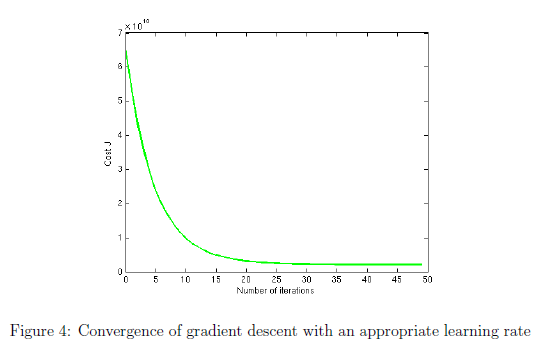

    If your graph looks very different, especially if your value of $J(\theta)$ increases or even blows up, use the control to adjust your learning rate and try again. We recommend trying values of the learning rate on a log-scale, at multiplicative steps of about 3 times the previous value (i.e., 0.3, 0.1, 0.03, 0.01 and so on). You may also want to adjust the number of iterations you are running if that will help you see the overall trend in the curve.

**Implementation Note:** If your learning rate is too large, $J(\theta)$ can diverge and 'blow up', resulting in values which are too large for computer calculations. In these situations, MATLAB will tend to return `NaNs`. `NaN` stands for 'not a number' and is often caused by undefined operations that involve $\pm \;\infty$.

**MATLAB Tip:** To compare how different learning learning rates affect convergence, it's helpful to plot `J` for several learning rates on the same figure. In MATLAB, this can be done by performing gradient descent multiple times with a `hold on` command between plots. Make sure to use the `hold off` command when you are done plotting in that figure. Concretely, if you've tried three different values of `alpha` (you should probably try more values than this) and stored the costs in `J1`, `J2` and `J3`, you can use the following commands to plot them on the same figure:

    The final arguments `'b'`,`'r'`, and `'k``'` specify different colors for the plots. If desired, you can use this technique and adapt the code below to plot multiple convergence histories in the same plot. 

% Run gradient descent:
% Choose some alpha value
alpha = 1;
num_iters = 50;

% Init Theta and Run Gradient Descent
theta = zeros(3, 1);
[~, J_history] = gradientDescentMulti(X, y, theta, alpha, num_iters);

**********
Debug purposes:
Theta computed from gradient descent:0.000000,0.000000

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To perform elementwise multiplication, use '.*'.

Error in gradientDescentMulti (line 28)
            theta_temp(column) = theta(column) -  alpha * (1/m) * sum( (X * theta - y) );


% Plot the convergence graph
plot(1:num_iters, J_history, '-b', 'LineWidth', 2);
xlabel('Number of iterations');
ylabel('Cost J');

Notice the changes in the convergence curves as the learning rate changes. With a small learning rate, you should find that gradient descent takes a very long time to converge to the optimal value. Conversely, with a large learning rate, gradient descent might not converge or might even diverge! 

    Using the best learning rate that you found, run the section of code below, which will run gradient descent until convergence to find the final values of $\theta$. Next, use this value of $\theta$ to predict the price of a house with 1650 square feet and 3 bedrooms. You will use value later to check your implementation of the normal equations. Don't forget to normalize your features when you make this prediction!

% Run gradient descent
% Replace the value of alpha below best alpha value you found above
alpha = 0.1;
num_iters = 400;

% Init Theta and Run Gradient Descent
theta = zeros(3, 1);
[theta, ~] = gradientDescentMulti(X, y, theta, alpha, num_iters);

% Display gradient descent's result
fprintf('Theta computed from gradient descent:\n%f\n%f\n%f',theta(1),theta(2),theta(3))

Theta computed from gradient descent:
0.000000
0.000000
0.000000


% Estimate the price of a 1650 sq-ft, 3 br house. You can use the same
% code you entered ealier to predict the price
% ====================== YOUR CODE HERE ======================

price = []; % Enter your price formula here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using gradient descent):
 $

### 3.3 Normal Equations

In the lecture videos, you learned that the closed-form solution to linear regression is


$$\theta = \left(X^T X\right)^{-1} X^T \vec{y} $$


    Using this formula does not require any feature scaling, and you will get an exact solution in one calculation: there is no "loop until convergence" like in gradient descent.

    Complete the code in `normalEqn.m` to use the formula above to calculate $\theta$, then run the code in this section. Remember that while you don't need to scale your features, we still need to add a column of 1's to the `X` matrix to have an intercept term ($\theta_0$) . Note that the code below will add the column of 1's to `X` for you.

% Solve with normal equations:
% Load Data
data = csvread('ex1data2.txt');
X = data(:, 1:2);
y = data(:, 3);
m = length(y);

% Add intercept term to X
X = [ones(m, 1) X];

% Calculate the parameters from the normal equation
theta = normalEqn(X, y);

% Display normal equation's result
fprintf('Theta computed from the normal equations:\n%f\n%f\n%f', theta(1),theta(2),theta(3));

Theta computed from the normal equations:
89597.909544
139.210674
-8738.019113

**Optional (ungraded) exercise: **Now, once you have found $\theta$ using this method, use it to make a price prediction for a 1650-square-foot house with 3 bedrooms. You should find that gives the same predicted price as the value you obtained using the model fit with gradient descent (in Section 3.2.1).

% Estimate the price of a 1650 sq-ft, 3 br house.
% ====================== YOUR CODE HERE ======================

price = [1, 1650, 3]*theta; % Enter your price forumla here

% ============================================================

fprintf('Predicted price of a 1650 sq-ft, 3 br house (using normal equations):\n $%f', price);

Predicted price of a 1650 sq-ft, 3 br house (using normal equations):
 $182861695.021679

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

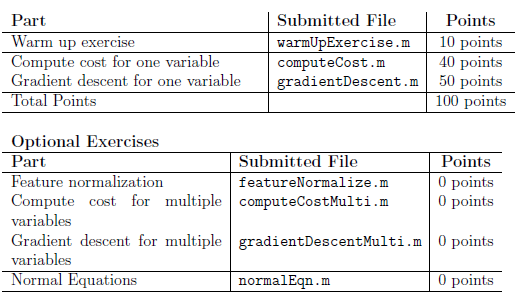

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.